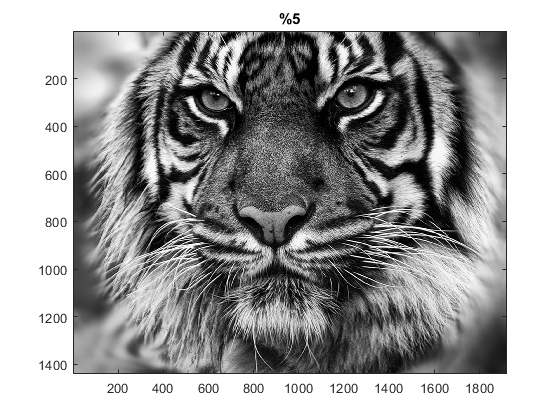

img = imread('tiger.jpg');
DCT_img = dct2(img);
[row , colomn] = size (DCT_img);
%%%%%
fimg5P = zeros(row, colomn);
ROW=floor(0.4*row);
COLOMN=floor(0.4*colomn);
fimg5P(1:ROW, 1:COLOMN)= DCT_img(1:ROW, 1:COLOMN);
f5P = idct2(fimg5P);
imwrite(uint8(f5P), 'tiger5P.jpg', 'JPG');
%%%%%%
fimg15P = zeros(row, colomn);
ROW2=floor(0.3*row);
COLOMN2=floor(0.3*colomn);
fimg15P(1:ROW2, 1:COLOMN2) = DCT_img(1:ROW2, 1:COLOMN2);
f15P = idct2(fimg15P);
imwrite(uint8(f15P), 'tiger15P.jpg', 'JPG');
%%%%%%
figure;
image(f5P);
colormap(gray(256));
title('%5');

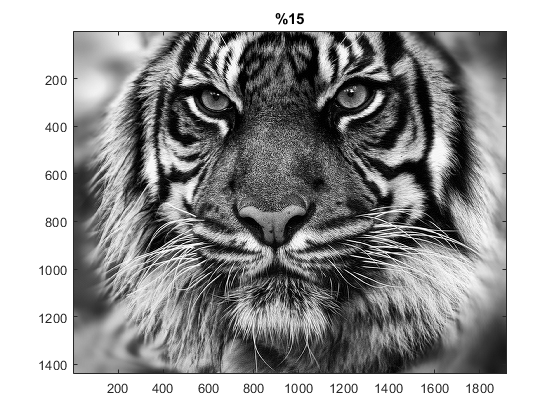

figure;
image(f15P);
colormap(gray(256));
title('%15');